Given

clear;
clc;
mass = 2000.0;
mu = 0.01;
dragCoeff = 0.3;
areaFront = 2.5;
airDensity = 1.2;
gravity = 10;
tireRadius = 0.4;
drivetrainEff = 0.9;
theta = 0;
graph = zeros(1, 12000);

Define Gear Ratio

%gearRatio = input("GearRatio?: " 
gearRatio = 9;

Loop for 120s every 0.01s

velocity = 0

velocity =      0


for i = 1:12000

Get Speeds

wheelSpeed = (velocity*60)/(pi*tireRadius);
motorSpeed = gearRatio*wheelSpeed;
motorTorque = 0;
if motorSpeed < 4000
    motorTorque = 250;
elseif motorSpeed <= 10000
    motorTorque = 250*(4000/motorSpeed);
elseif motorSpeed > 10000
    motorTorque = 0;
end
forwardTireForce = motorTorque*gearRatio*drivetrainEff/tireRadius;

Calculate Forces

rollingResist = mass*mu*gravity;
aeroResist = 0.5*airDensity*areaFront*velocity*velocity*dragCoeff;
gradientResistance = mass*gravity*sind(theta);
totalForce = forwardTireForce-rollingResist-aeroResist-gradientResistance;

Calculate Acceleration from f=ma and update velocity

acceleration = totalForce/mass;
velocity = velocity + acceleration*0.01;
graph(i) = velocity;
end

Plot Graph

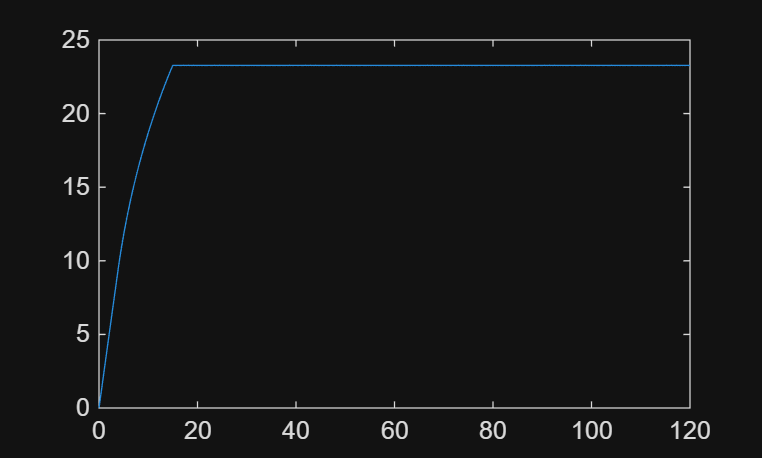

plot((1:length(graph))/100,graph)